## Generate 4-QAM Image Data

input_image = 'data\einstein.jpg';
pilot_seq_len = 32; % length of known pilot sequence
Fs = 2000000; % sampling frequency

%generate RRC Pulse
T = 50; % Symbol Period
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 

hamming_on = 0;
[imBW,dataQ,data] = image_to_data(input_image,hamming_on);
% imshow(imBW);

## Generate TX Data

% txname='data\test.dat';
% x = build_tx_file(txname, dataQ, pilot_seq_len, rrc, T)

## Decode RX Data

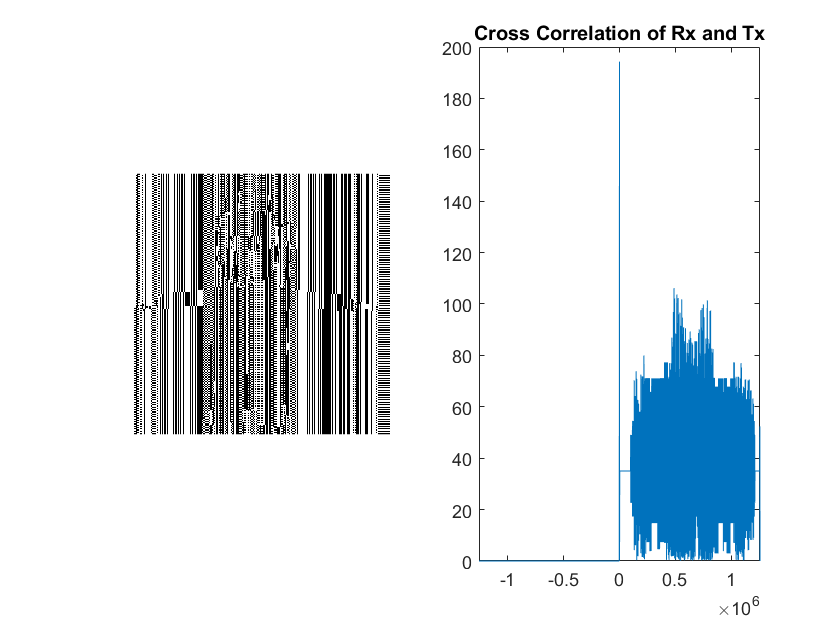

    "Start Position: "    "0"



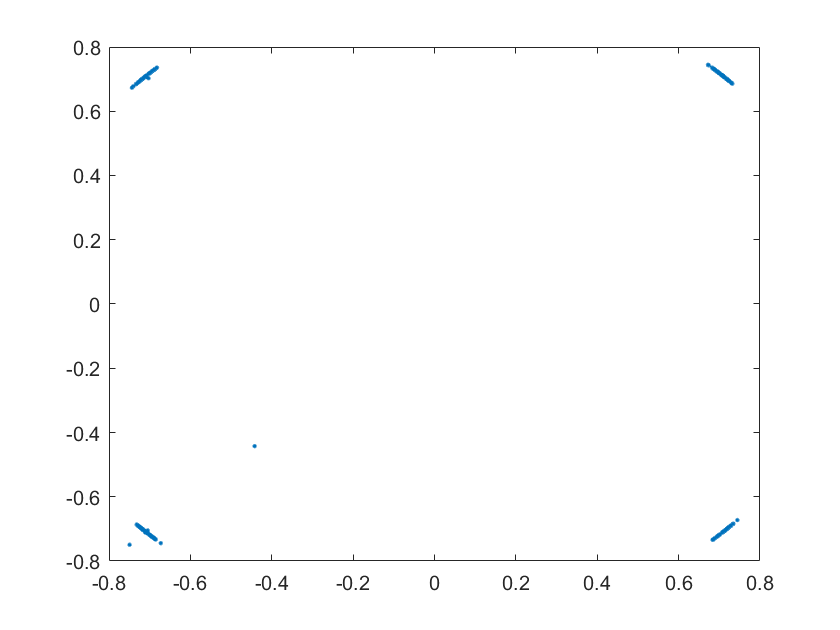

txname='data\tx_image_einstein.dat';
rxname = 'data\tx_image_einstein.dat';
[rxQ, errRate] = qpsk(txname, rxname, length(dataQ), T, rrc, Fs, pilot_seq_len);

errRate

errRate = "HAHA"

## Printing Image

% l = 1:length(rxQ);
% rxQ2 = rxQ.*exp(1i*l-pi/2);
% phase_options
% for 1:
rxQsigned = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQsigned);
rxH = errorCorrect(rxBinary);
rxH = rxH(1:end);
rxIm = reshape(rxBinary, 216, []);
error_rate = compute_qpsk_error(data,rxBinary)

error_rate = 0.2104

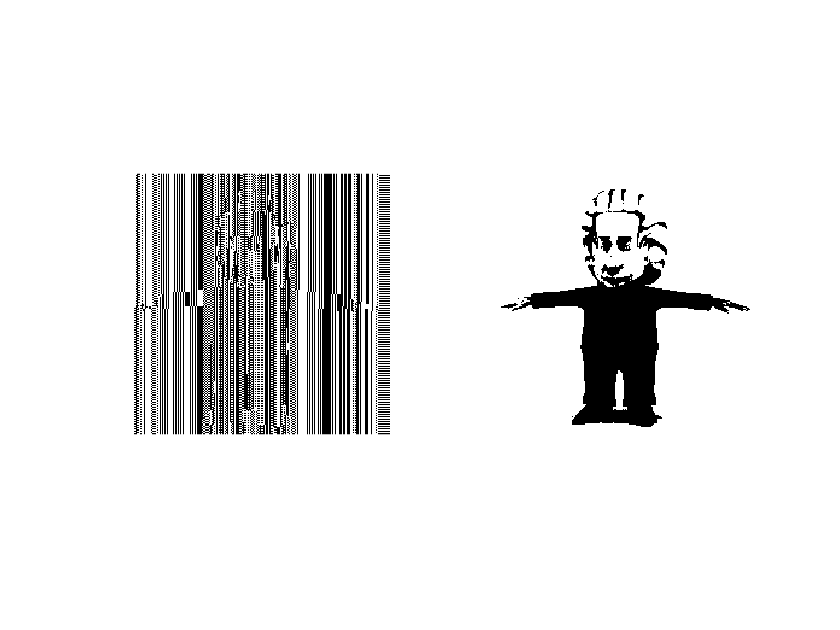

subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)